## **Received Power PR**

function P=PR(lambda,PD,h_k,hD,PC)
syms N0 
P=lambda*(PD*hD+PC*h_k+N0);
end

## **Throughput equation for CUE links**

function T=Throughput_C(PD,h_iB,h_kc,P_kc)
syms N0 N1
T=log2(1+(P_kc*h_kc)/(PD*h_iB+N0+N1));
end

## **Throughput equation for D2D links.**

For this function, we take the power splitting ratio lambda, transmission power fo D2D links PD, transmission of CUE, interference hki, and hD

function T=Throughput_D(lambda,PD,P_kc,h_ki,hD)
syms N0 N1
T=log2(1+((1-lambda)*(PD*hD))/((1-lambda)*(P_kc*h_ki+N0)+N1));
end

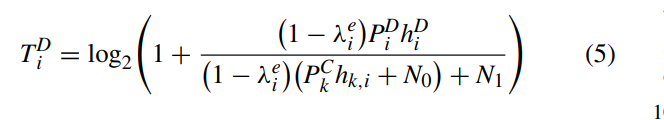

## Piecewise Energy Harvesting model

we take a received power as an input argument for the Energt Harvesting model where the received power is from different segemnts,

then we compare each segment's received power and compare it to the threshold power Pth, then we can get the ouput Harvested power  **E.**

function E=Eenergy_harvesting(PR)
syms k b Pmax Pth L
 if PR>Pth(1) &&  PR<Pth(2)
     E=0;
 % Traverse the Pth array then compare each segment's power
 elseif PR>Pth(2) && PR<Pth(L+1)
     for j=2:L
         if PR>Pth(j) && PR<Pth(j+1)
             E=k(j)*PR+b(j);
             break;
         end
     end
 else
     E=Pmax;
 end
 
end

##  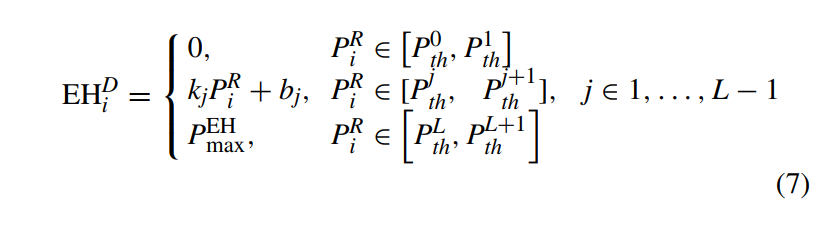

## **Total Energy Consumption EC_iD**

For this function we want to find the total energt consumption EC, so the basic idea will be taking the transmission power PD , circuit power consumption  P_iR and the harvested power EH, and the equatio in the picture below will be used to caculate the energy consumption, the EH can be

obtained from the function **EH**

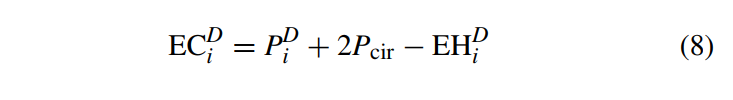

function E=Energy_Consumption(PD,P_ir,EH)
    E=PD+2*P_ir-EH;
end

## **Prematching Algorithm**

This algorithm will be used to match every possible link i of D2D links with CUE link to divide the D2D links into two different groups:

- SWIPT-Eanbled D2D links **EhaD**

- Non EH D2D group which can not perform SWIPT **InfD**

First create three different empty sets for output and they are **EhaD,InfD,SiD. **And we take maximum value of Transmission power of D2D links **Pmax**

**, **minimum value of Throughput of D2D lins **TminD, **transmission power of CUE link K which is always the same in this reference paper, D2D links set noted as **D **, CUE links noted as **C. **Thresholds for received power **P_iR **as the input arguments, then we can start with the prematching algorithm:

- First we need to traverse the D2D links **D **to scan every possible link i

- Then for the **ith** segment of set **D, **we need to figure out if the current segment of CUE match with the segment i of D

- To finish the matching , we need to meet two requiremnts

                1.The power splitting ratio lambda for each segment i is not supposed to exceed 1

                2.The maximum value of Throughput of each  D2D link **i ** is  supposed to be greater than the minimum value D2D links: **T_iD_max>T_min_D**

          4.So for each segment of CUE set **k**, if this segment doesn't meet neither one of the requirements above, then the partner selection set **S_iD **will remove the current k segment, in the code it was noted as **0.**

          5. So for each segment of D2D links **i, **it will match all the segments of the CUE sets to figure out if the current segment matches the current segment of D2D link i

         6. Once finishing scanning every segment **k **of CUE set, it will check if the partner selection set **S_iD **is empty, if so, that means there is no segment in CUE set matcing the current segment i then, the current segemnt i will be added into the Non-EH group **InfD, **if not, it means there is at least one segment **k **in the CUE set which can match the current segment **i **of D2D link, then it will be added into the SWIPT-Enabled group **EhaD. (if at each iteration of segment i of D2D link, if the partner selection set is not all zeros it means it has at least one segment which will match the current segment  i of the whole D2D link)**

        7.Afther the prematching algorithm, we shall get a SWIPT-Enabled D2D link set **EhaD** which has some links that can perform SWIPT and the non-EH D2D group which can not perform SWIPT. The final partner selection set will have the remaining segments which can match the corresponding D2D link, E.g.if the final SiD=[ 1 2 3 4 5 0 0; 1 0 3 4 5 0 7; 1 2 0 4 0 0 7 ...]; That means tha for the first segemnt of D2D links, the CUE set has 5 links which can match the segment **1. ** And for the segment **2 **of D2D links, the CUE sets has 5 links which can match the segment 2, the same for the other segments of D2D links,assuming CUE set has 7 segments in this case(**That is why a CUE segment can appear in more than one partner selection according to the reference paper.**)

function [SiD,InfD,EhaD] = Prematch(D,C,PC,Pth1,Pmax,TminD)
% set the channel responses of D2D link and channel responses from D2D link
% and CUE link
syms hD h_interference_D2D_CUE 
syms lambda_min T_max

%initialize minimum power splitting ratio, it is supposed to be an array
lambda_min=[];

%initialize maximum Throughpu
T_max=[];
%Non-EH D2D links
InfD=[];
%SWIPT-Eanbled communication system
EhaD=[];
for i=1:size(D,2)
    for k=1:size(C,2)
        %\lamda ie
        SiD(i,:)=C;
        lambda_min(i)=Pth1/(Pmax*hD(i)+PC* h_interference_D2D_CUE(k,i)+N0);
        T_max(i)=log2(1+(Pmax*hD(i))/(PC*h_interference_D2D_CUE(k,i)+N0+(N1)/1-lambda_min(i)));
        %compare the minimum power splitting ratio and maximum
        %Throughput,if both of the requiremnts can not be met, then the k
        %will be removed from the selection set.
        if lambda_min(i)>1 || T_max(i)<TminD
            SiD(i,k)=0;
        end 
    end
    %After the CUE set was scanned, then check if the selection set is
    %empty,if so add the segment to the non EH group if not, then add it to
    %the Enabled SWIPT D2D groups.
    temp=SiD(i,:);
    if nnz(~temp)==size(C,2)
        InfD(end+1)=i;
        EhaD(end+1)=0;
    elseif nnz(~temp)~=size(C,2)
        EhaD(end+1)=i;
        InfD(end+1)=0;
    end
end
            
        
end

## Outer loop Algorithm

function [Pid_optimal,lambda_optimal,EE_optimal]=Outer(EhaD,SiD,lambda,P_ijD,EE_ijD)
%first of all, we need to search the whole SWIPT-Enabled D2D communication
%system, then search for the partner selection set obtained by the
%pre-matching algorithm. Then we set Nmax segments first then search them,
%for each segment, we need to find the maxmimum Energy Efficiency of each
%segment and the j value at which Energy efficiecny reaches its maximum
%value, then update the optimal value of J, transmission power PiD_optimal,
%power plitting ratio lambda_optimal, and ofcourse the energy efficiency EE_optimal
syms Nmax
Pid_optimal=[];
lambda_optimal=[];
EE_optimal=[]
for i =1:size(Ehad,2)
    for k=1:size(SiD,2)
        for j=1:Nmax
            [argvalue,argmax]=max(EE_ijD(i:j));
            j_optimal=argmax;
            Pid_optima(i)=P_ijD(i,j_optimal);
            lambda_optimal(i)=lambda(i,j_optimal);
            EE_optimal(i)=EE_ijD(i,j_optimal);
        end
    end
end
end


## Inner loop Algorithm

First of all we need to determine the maximum segments before we get,started with the algorithm, according to the piecewise function of EH model in the picuture below. So to get the maximum number of segments, we need to first figure out which segment of Pth which is the threshold power of PiR belongs to, by using the equation below, we can get the maximum value of the received power PiR then we need to compare it to the piecewise model and figureout the which segment it blongs to then we can get the maximum number of segemnts.

So first use the euqation to obtain the mamimum PiR:

1. Scan the Enabled SWIPT D2D links, set each segemnt's maximum value of received power to the array.

2. Then find the ponint where the received  power reches the maximum value among each segemnt's maximum value.

3. Then the corresponding maximum value among all of these "maximum value" will be used to compare to the piecewise model by traversing through the whole threshold power array , **but remember that the number of the segment in the linear piecewise Energy Harvesting model does not increase as the received increase, so at the end of the loop we should find maximum value of the N_segment array)**

Then we can start to implement the algorithm with my obtained maximum value of segments:Nmax.

- First we start to traverse the whole SWIPT-Enabled D2D links, scan each segment i

- Then to match every possible CUE link j, first scan every CUE in the Partner selection set k,

- Then to scan each segement of every segemnt j in the piecewise EH model.

function [lambda_ij,P_ij,EE_ij]=Inner(EhaD,S_iD)
syms Initial_QiD Initial_P_iD K_intercept B_intercept optimal_lambda 
syms Q
syms EC EH EE
syms TD TC T_min_D T_min_C
syms N0 N1
syms P_th PC PD P_ir P_iR Pmax P_th Pmax
syms hD h_k h_C hB
syms a1 a2 a3 K G H J
syms m1 m2 m3 m4 m5 m6 b1 b2 b3 b4 e_ta  XN YN g phi theta P1 
syms s1 s2 s3 s4 s5
syms beta alpha gamma delta in 
%initialize step size
s1=1.0000e-05;
s2=1.0000e-05;
s3=1.0000e-05;
s4=1.0000e-05;
s5=1.0000e-05;
%initialize EE
EE_ij=[];
%initialize Throughput of D2D links
TD=[];

%initialize Throughput of CUE links
TC=[];
%initialize total energy consumption EC
EC=[];
%initialize Energy_harvesting power
EH=[];
%initialize received power P_iR
P_iR=[];
%According to the reference paper, they set a very small positive value to
%initial QiD
Q=[];
Q(1,1)=Initial_QiD;
%Set the iteration step
t=1;

%Set the allowed iteration number,this will be changed later.
I=0;
Psi=0;
%assign the initial value of transmission power of D2D link to the set.Then
%for each iteration of the EhaD, the i_th link's power splitting ratio
%will be added to the set.
optimal_P_iD=[];
optimal_P_iD(1,1)=Initial_P_iD;
PD(1)=Initial_P_iD;
P_iR_max=[];
Nmax=1;
%set the maximum value for each segment of received power P_iR
for i=size(EhaD,2)
    for k=1:size(S_iD,2)
        if(SiD(i,k)~=0)
           P_iR_max(i,k)=Pmax*hD(i)+PC*h_k(i,k)+N0;
        else
           P_iR_max(i,k)=0;
        end
    end
end
 [argvalue,argmax]=max(P_iR_max(:));
 
 %traverse the array Pth to find the maximum number of segemnts Nmax
for p=1:size(P_th,2)
    if argvalue>P_th(p)
        Nmax=Nmax+1;
    elseif argvalue<P_th(p)
        break;
    end
end
%initialize the power splitting ratio and transmission power
optimal_lambda=[];

 %traverse the Enabled SWITPT D2D links array,and for each iteration, loop through the partner selection set
 %we obtained from the prematching algorithm, and loop through each segment
 %until it reaches the maximum value for each iteration.
for i=1:size(EhaD,2)
    for k=1:size(S_iD,2)
        for j=1:Nmax
            %obtain optimal power splitting ratiom and find the maximum
            %value of it
            G=PD(i,1) *hD(i);
            H=PC(k)*h_k(i)+N0;
            K=beta+(Q(i,t)+in)*K_intercept(j)*(G+H);
            J=G*N1*log2(exp(1))*(1+gamma);
            a1=K*(G*H+H*H);
            a2=K*(G+2*H)*N1;
            a3=K*N1*N1-J;
            lam1=(-a2+sqrt(a2*a2-4*a1*a3))/(2*a1);
            lam2=(-a2-sqrt(a2*a2-4*a1*a3))/(2*a1);
            lam3=0;
            optimal_lambda_matrix_i=[lam1 lam2 lam3];
            optimal_lambda(i,t)=max(optimal_lambda_matrix_i);
            %Then while t is less than the allowed maximum value of
            %iteration, we need to cacualte each segment of transmission
            %power. And remember this allowed maximum number of iterations
            %should be established later.
            while t<I
                n=[0 1 2];
                m1=(1+gamma)*hD(i)*log2(exp(1));
                m2=PC(k)*h_k(i)+N0+((N1)/(1-optimal_lambda(i,t)));
                m3=Q(i,t)*(1+(1-optimal_lambda(i,t))*e_ta*hD(i)-(K_intercept(j)*hD(i)))+alpha-(in*optimal_lambda(i,t)*K_intercept(j)*hD(i));
                m4=PC(k)*h_C(k)*hB(i)*log2(exp(1))*delta;
                m5=N0+N1;
                m6=PC(k)*h_C(k);
                b1=m3*hD(i)*hB(i)*hB(i);
                b2=(2*m3*m5+m3*m6)*hD(i)*hB(i)-(m1-m2*m3)*hB(i)^2;
                b3=(m3*m5*m5+m3*m5*m6+m4)*hD(i)-(2*m1*m5+m1*m6-2*m2*m3*m5-m2*m3*m6)*hB(i);
                b4=m2*m4+m2*m3*m5*m5+m2*m3*m5*m6-m1*m5*m5-m1*m5*m6;
                XN=(-m2/(3*m1));
                YN=(2*b2^3)/(27*b1^2)-((b2*b3)/(3*b1))+b4;
                g=2*b1*sqrt((b2*b2-3*b1*b3)/(9*b1*b1))^3;
                phi=(1/3)*acos(-YN/g);
                theta=sqrt((m2*m2-3*m1*m3)/(9*m1*m1));
                P1=piecewise(YN^2>g^2,XN+((-YN+sqrt(YN^2-g^2))/(2*a1))^(1/3),YN^2<g^2,XN+2*theta*cos(phi-n*(2*pi)/3),XN-theta | XN+2*theta);
                PD(i,t+1)=max(0,P1);
                
                %update the power splitting ratio for next iteration
                G= PD(i,t+1)*hD(i);
                H=P_kc*h_k(i)+N0;
                K=beta+(QD(i,t)+in)*K_intercept(j)*(G+H);
                J=G*N1*log2(exp(1))*(1+gamma);
                a1=K*(G*H+H*H);
                a2=K*(G+2*H)*N1;
                a3=K*N1*N1-J;
                lam1=(-a2+sqrt(a2*a2-4*a1*a3))/(2*a1);
                lam2=(-a2-sqrt(a2*a2-4*a1*a3))/(2*a1);
                lam3=0;
                optimal_lambda_matrix_i=[lam1 lam2 lam3];
                optimal_lambda(i,t+1)=max(optimal_lambda_matrix_i);
                
                %Then update the new Throughput with new obtained optimal
                %value of transmission power and and power splitting ratio
                
                P_iR(i)=PR(optimal_lambda(i,t+1),PD(i,t+1),h_k(i),hD(i),PC(k));
                EH(i)=Eenergy_harvesting(P_iR(i));
                EC(i)=Energy_Consumption(PD(i,t+1),p_ir,EH(i));
                TD(i)=Throughput_D(optimal_lambda(i,t+1),PD(i,t+1),PC(k),h_k(i),hD(i));
                TC(i)=Throughput_C(PD(i,t+1),hB(i),h_C(k),PC(k))
                if TD(i)-(Q(i,t)*EC(i))>Psi
                    Q(i,t+1)=TD(i)/EC(i);
                    %imagine this as an array which has t elements, and the
                    %point is that we need to figure out which is the
                    %biggest one
                    alpha=max(alpha+s1.*(PD(i)));
                    beta=max(beta+s2.*(optimal_lambda(i)-1));
                    gamma=max(gamma-s3.*(TD(i)-T_min_D));
                    delta=max(delta-s4.*(TC(i)-T_min_C));
                    in=max(in-s5.*(P_iR(i)-P_th(2)));
                    continue
                else
                    PD(i,j)=PD(i,t+1);
                    P_ij=PD(i,j);
                    optimal_lambda(i,j)=optimal_lambda(i,t+1);
                    lambda_ij=optimal_lambda(i,j);
                    EE(i,j)=Q(i,t);
                    EE_ij=EE(i,j);
                end
                t=t+1;
            end
            
        end
    end
end
%Then find the at which point maximum value of the setted Pir_max array

end